# Lifting line theory calculation for propellers

Local chord determination by N= 100 lcoations of phi

Example given with N= 6

For a given data chords of propellers according to the image:

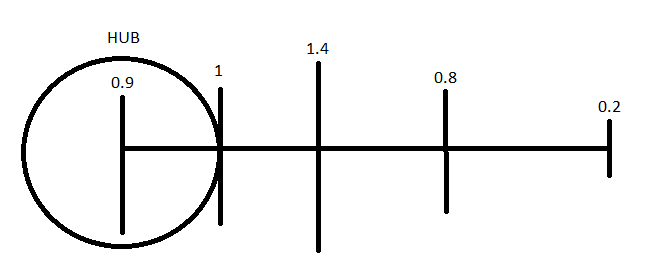

% Inputs:
% wing geometry parameters:
%   a0= sectional lift ideal curve slope 2*pi
%   AR= Aspect ratio
%   taper_ratio= taper of wing
%   alpha_zl= angle where there's no lift
%   alpha= geometric angle of attack
%   local_chord= chord length according to phi
% Outputs:
%   CLwing, CDinduced
%
%   Defined locations of phi: 100 locations for angle
%
%   function [CLwing, CDinduced, Cleff]= LLT(wing_span, surface_area, taper_ratio, alpha_zl, alpha)
%   Eval function when the code is finished
wing_span= 4;
surface_area= 
alpha= 4;
alpha_zl= -1.2;
alpha= alpha*(pi/180);
alpha_zl= alpha_zl*(pi/180);
%   VAriables to be determined
a0= 2*pi;
N= 100;
for n= 1:N
    phi(n)= n*pi/(2*N);
end
%   Definition of matrixes (I think its not neccesary to define the matrixes first)
A= zeros(N,N);
B= zeros(N,1);

%   Definition of Matrix A&B
for i= 1:N
    mu= 